[Heart Disease - UCI Machine Learning Repository](http://archive.ics.uci.edu/dataset/45/heart+disease)

close all; clear; clc;

% Specify the path to your .data file
filePath = 'data/heart+disease/processed.cleveland.data';

% Use importdata to load the data
data = importdata(filePath);


features = data(:, 1:13)

features =    63.0000    1.0000    1.0000  145.0000  233.0000    1.0000    2.0000  150.0000         0    2.3000    3.0000         0    6.0000
   67.0000    1.0000    4.0000  160.0000  286.0000         0    2.0000  108.0000    1.0000    1.5000    2.0000    3.0000    3.0000
   67.0000    1.0000    4.0000  120.0000  229.0000         0    2.0000  129.0000    1.0000    2.6000    2.0000    2.0000    7.0000
   37.0000    1.0000    3.0000  130.0000  250.0000         0         0  187.0000         0    3.5000    3.0000         0    3.0000
   41.0000         0    2.0000  130.0000  204.0000         0    2.0000  172.0000         0    1.4000    1.0000         0    3.0000
   56.0000    1.0000    2.0000  120.0000  236.0000         0         0  178.0000         0    0.8000    1.0000         0    3.0000
   62.0000         0    4.0000  140.0000  268.0000         0    2.0000  160.0000         0    3.6000    3.0000    2.0000    3.0000
   57.0000         0    4.0000  120.0000  354.0000         0         0  

features = transpose(features)

features =    63.0000   67.0000   67.0000   37.0000   41.0000   56.0000   62.0000   57.0000   63.0000   53.0000   57.0000   56.0000   56.0000   44.0000   52.0000   57.0000   48.0000   54.0000   48.0000   49.0000   64.0000   58.0000   58.0000   58.0000   60.0000   50.0000   58.0000   66.0000   43.0000   40.0000   69.0000   60.0000   64.0000   59.0000   44.0000   42.0000   43.0000   57.0000   55.0000   61.0000   65.0000   40.0000   71.0000   59.0000   61.0000   58.0000   51.0000   50.0000   65.0000   53.0000
    1.0000    1.0000    1.0000    1.0000         0    1.0000         0         0    1.0000    1.0000    1.0000         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0    1.0000         0    1.0000         0    1.0000    1.0000    1.0000        

labels = data(:, 14)

labels =      0
     2
     1
     0
     0
     0
     3
     0
     2
     1


% class(labels)
labels = categorical(labels);
% categories(labels)
labels = onehotencode(labels,2)

labels =      1     0     0     0     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     0     0     0     1     0
     1     0     0     0     0
     0     0     1     0     0
     0     1     0     0     0


labels = transpose(labels)

labels =      1     0     0     1     1     1     0     1     0     0     1     1     0     1     1     1     0     1     1     1     1     1     0     0     0     1     1     1     1     0     1     0     0     1     1     1     0     0     0     1     0     1     1     1     0     0     1     0     1     1
     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0
     0     1     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0    

% labels = cast(labels, 'int8')

% Neural Network Architecture
hiddenLayerSize = 100; % Experiment with different values
net = patternnet(hiddenLayerSize);
net.trainFcn = 'trainlm'; % Experiment with different training functions
net.divideFcn = 'dividerand'; % Random division for training and testing
net = configure(net,features,labels);
view(net)


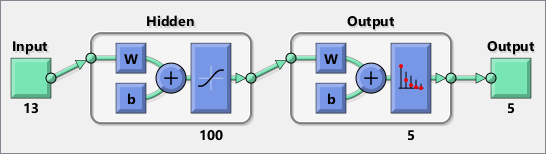

% Training
[net, tr] = train(net, features, labels);

% Evaluate on the test set
testFeatures = features(:, tr.testInd);
testLabels = labels(:, tr.testInd);
predictedLabels = net(testFeatures);

% Calculate accuracy
accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);
accuracy

accuracy = 0.4615

% Hyperparameter Tuning (Example: Number of hidden layers)
hiddenLayerSizes = [1,2,3,4,5,6,7,8,9, 10, 15]; % Experiment with different sizes

for i = 1:length(hiddenLayerSizes)
    hiddenLayerSize = hiddenLayerSizes(i);
    net = patternnet(hiddenLayerSize);
    net = configure(net,features,labels);
    testFeatures = features(:, tr.testInd);
    testLabels = labels(:, tr.testInd);
    predictedLabels = net(testFeatures);
    accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);
    disp(['Hidden Layer Size: ', num2str(hiddenLayerSize), ', Accuracy: ', num2str(accuracy)]);
end

Hidden Layer Size: 1, Accuracy: 0.69231
Hidden Layer Size: 2, Accuracy: 0.076923
Hidden Layer Size: 3, Accuracy: 0.30769
Hidden Layer Size: 4, Accuracy: 0.15385
Hidden Layer Size: 5, Accuracy: 0.076923
Hidden Layer Size: 6, Accuracy: 0.23077
Hidden Layer Size: 7, Accuracy: 0.46154
Hidden Layer Size: 8, Accuracy: 0.15385
Hidden Layer Size: 9, Accuracy: 0.15385
Hidden Layer Size: 10, Accuracy: 0
Hidden Layer Size: 15, Accuracy: 0.23077


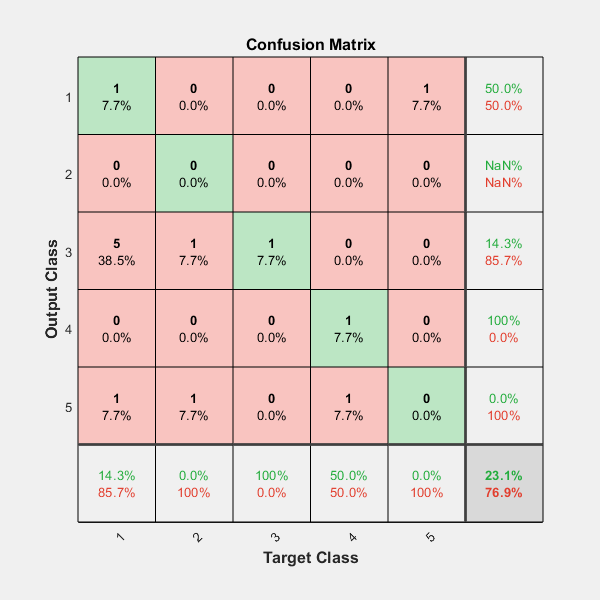

% Analysis and Visualization
figure;
plotconfusion(testLabels, predictedLabels);
title('Confusion Matrix');

% Hyperparameter Tuning
hiddenLayerSizes = 1:5;
trainingFunctions = {'trainlm', 'traingd', 'traingda', 'traingdm', 'traingdx'};
optimizationAlgorithms = {'sgd', 'adam', 'rmsprop', 'sgdm', 'sgdx'};

bestAccuracy = 0;
bestParams = struct();

for hiddenLayerSize = hiddenLayerSizes
    for trainFcn = trainingFunctions
        for optimAlgorithm = optimizationAlgorithms
            net = patternnet(hiddenLayerSize);
            net.trainFcn = trainFcn{1};
            net.divideFcn = 'dividerand'; % Random division for training and testing

            % Training
            [net, tr] = train(net, features, labels);

            % Evaluate on the test set
            testFeatures = features(:, tr.testInd);
            testLabels = labels(:, tr.testInd);
            predictedLabels = net(testFeatures);

            % Calculate accuracy
            accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);

            % Display results
            disp(['Hidden Layer Size: ', num2str(hiddenLayerSize), ...
                ', Train Function: ', trainFcn{1}, ...
                ', Optim Algorithm: ', optimAlgorithm{1}, ...
                ', Accuracy: ', num2str(accuracy)]);

            % Update best parameters if current model is better
            if accuracy > bestAccuracy
                bestAccuracy = accuracy;
                bestParams.hiddenLayerSize = hiddenLayerSize;
                bestParams.trainFcn = trainFcn{1};
                bestParams.optimAlgorithm = optimAlgorithm{1};
            end
        end
    end
end

Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.38462


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.30769


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.46154


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.38462


Hidden Layer Size: 1, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.76923
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.69231
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.38462
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.53846
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.30769
Hidden Layer Size: 1, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.69231
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.38462
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.84615
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.61538
Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.69231
Hidden Layer Size: 1, T

Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.53846


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.53846


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.38462


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.46154


Hidden Layer Size: 2, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.84615
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.69231
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.61538
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.61538
Hidden Layer Size: 2, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.53846
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.76923
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.69231
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.46154
Hidden Layer Size: 2, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.61538
Hidden Layer Size: 2, T

Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.23077


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.38462


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.61538


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.53846


Hidden Layer Size: 3, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.53846
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.69231
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.61538
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.38462
Hidden Layer Size: 3, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.23077
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.53846
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.61538
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.53846
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.61538
Hidden Layer Size: 3, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.38462
Hidden Layer Size: 3, T

Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.61538


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.76923


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.23077


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.61538


Hidden Layer Size: 4, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.61538
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.30769
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.30769
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.46154
Hidden Layer Size: 4, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.38462
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.46154
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.53846
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.53846
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.53846
Hidden Layer Size: 4, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 4, T

Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgd, Accuracy: 0.53846


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: adam, Accuracy: 0.46154


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: rmsprop, Accuracy: 0.69231


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgdm, Accuracy: 0.76923


Hidden Layer Size: 5, Train Function: trainlm, Optim Algorithm: sgdx, Accuracy: 0.76923
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgd, Accuracy: 0.30769
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: adam, Accuracy: 0.53846
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: rmsprop, Accuracy: 0.53846
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgdm, Accuracy: 0.53846
Hidden Layer Size: 5, Train Function: traingd, Optim Algorithm: sgdx, Accuracy: 0.61538
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgd, Accuracy: 0.61538
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: adam, Accuracy: 0.53846
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.61538
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgdm, Accuracy: 0.69231
Hidden Layer Size: 5, Train Function: traingda, Optim Algorithm: sgdx, Accuracy: 0.53846
Hidden Layer Size: 5, T

disp(['Best Parameters - Hidden Layer Size: ', num2str(bestParams.hiddenLayerSize), ...
    ', Train Function: ', bestParams.trainFcn, ...
    ', Optim Algorithm: ', bestParams.optimAlgorithm, ...
    ', Best Accuracy: ', num2str(bestAccuracy)]);

Best Parameters - Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: rmsprop, Best Accuracy: 0.84615


% Use the best parameters
bestHiddenLayerSize = bestParams.hiddenLayerSize;
bestTrainFcn = bestParams.trainFcn;
bestOptimAlgorithm = bestParams.optimAlgorithm;

% Create and train the final model
finalNet = patternnet(bestHiddenLayerSize);
finalNet.trainFcn = bestTrainFcn;
finalNet.divideFcn = 'dividerand'; % Random division for training and testing

% Training
[finalNet, tr] = train(finalNet, features, labels);

% Evaluate on the test set
testFeatures = features(:, tr.testInd);
testLabels = labels(:, tr.testInd);
predictedLabels = finalNet(testFeatures);

% Calculate accuracy
accuracy = sum(vec2ind(predictedLabels) == vec2ind(testLabels)) / length(testLabels);

disp(['Final Model - Hidden Layer Size: ', num2str(bestHiddenLayerSize), ...
    ', Train Function: ', bestTrainFcn, ...
    ', Optim Algorithm: ', bestOptimAlgorithm, ...
    ', Accuracy: ', num2str(accuracy)]);

Final Model - Hidden Layer Size: 1, Train Function: traingda, Optim Algorithm: rmsprop, Accuracy: 0.76923
